# 液压系统基本形式

## 开式系统

油箱与大气相通

C2_1_openTank

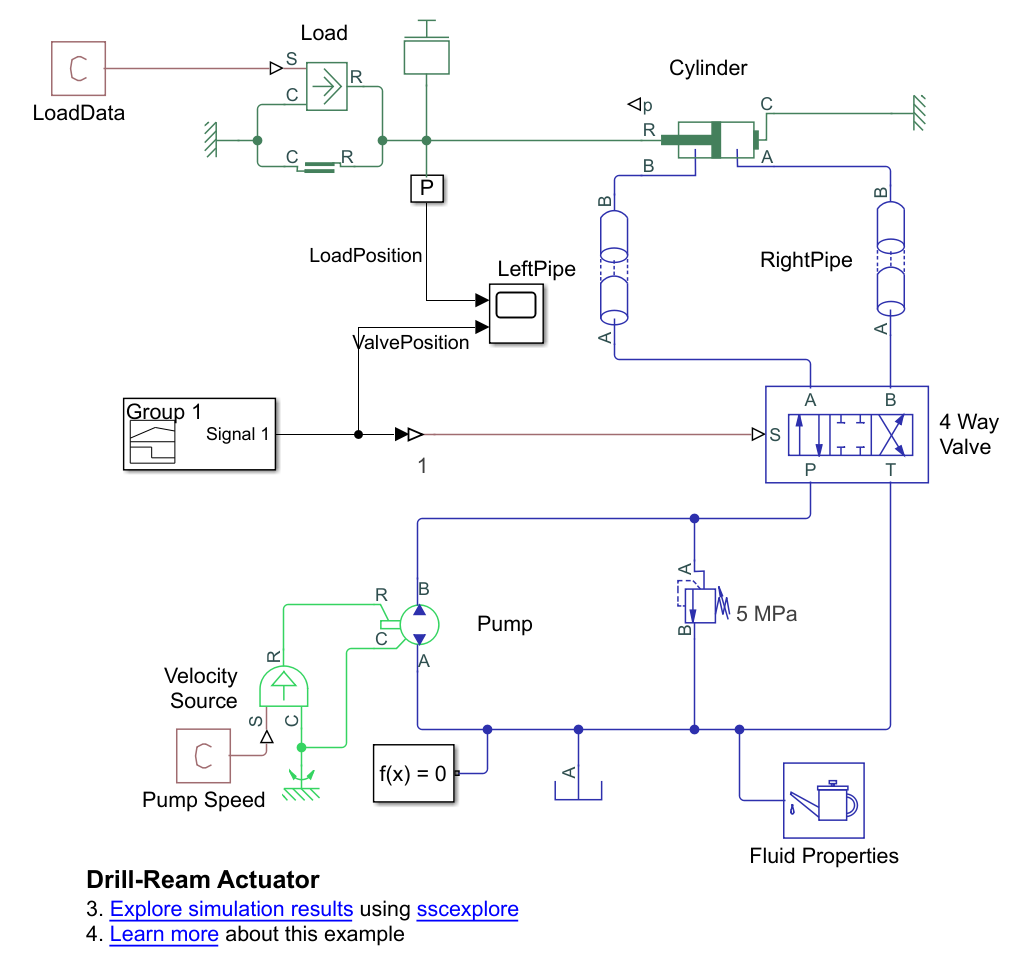

溢流阀限制系统压力摆正系统安全。

通过换向阀来保证液压缸的运动、换向以及停止。

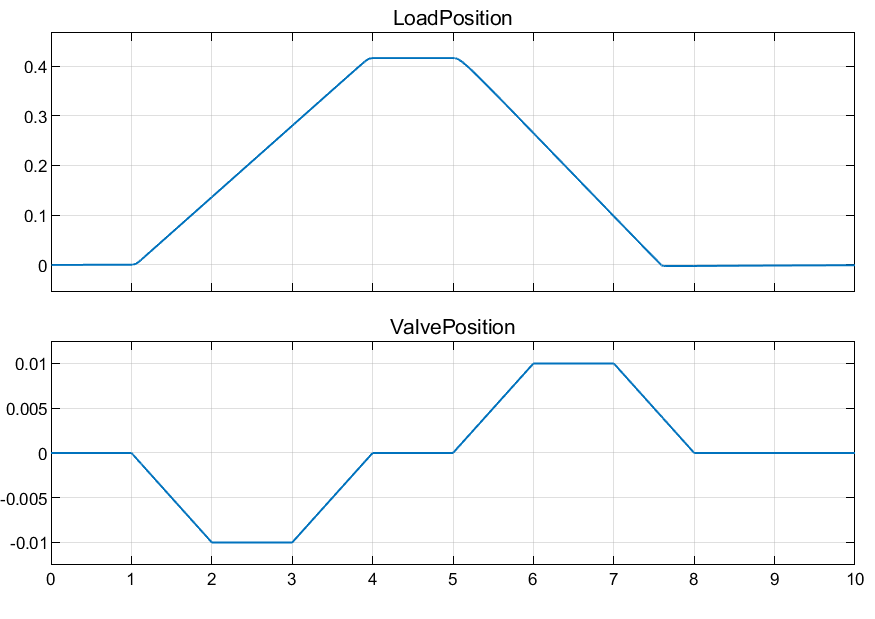

## 闭式系统

低版本打开：

web(fullfile(docroot, 'physmod/hydro/ug/hydrostatic-transmission-il.html'))

C2_4_closeLoop

主泵输出液压油直接进入马达入口，而马达回油直接进入泵吸油口，形成闭环回路。

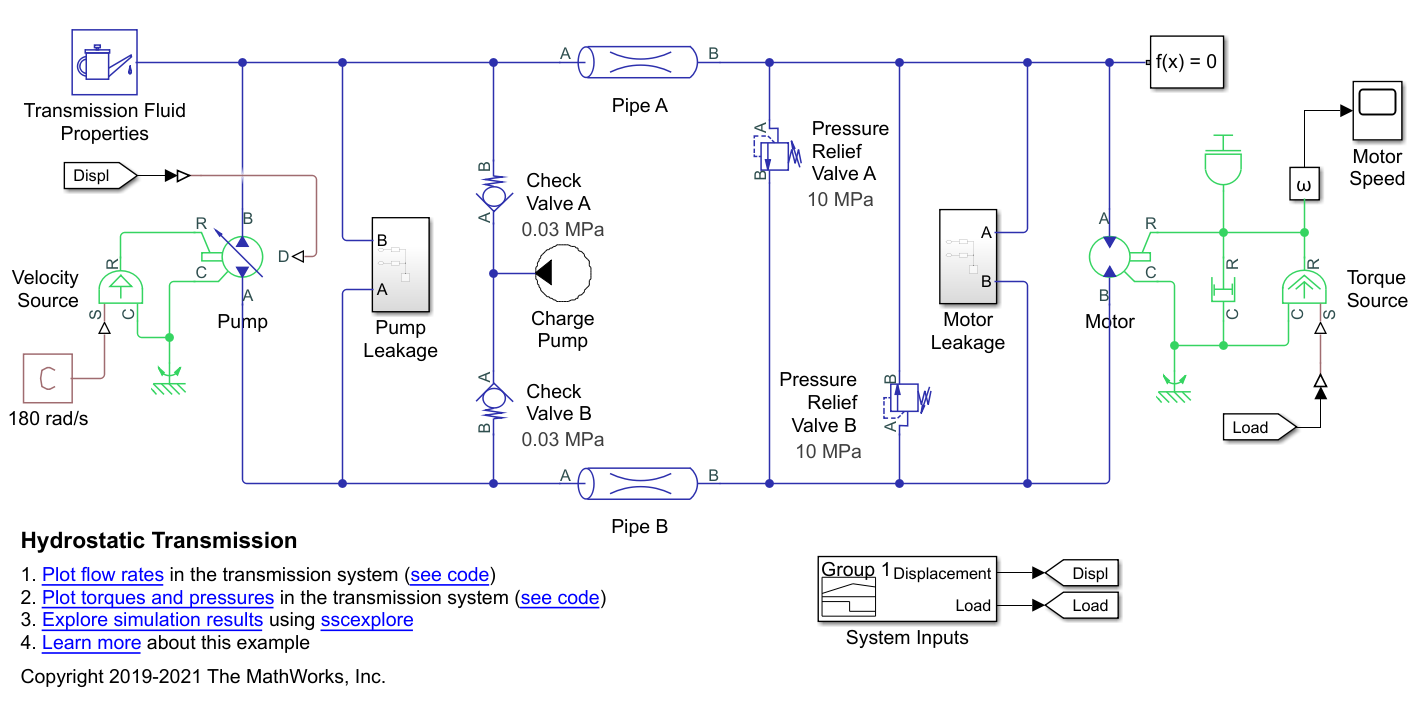

### 1. 马达转速调节

液压马达转速的调节是靠泵的排量调节完成。这里的马达换向不是靠换向阀，也是靠主泵的双向变量泵特性完成。

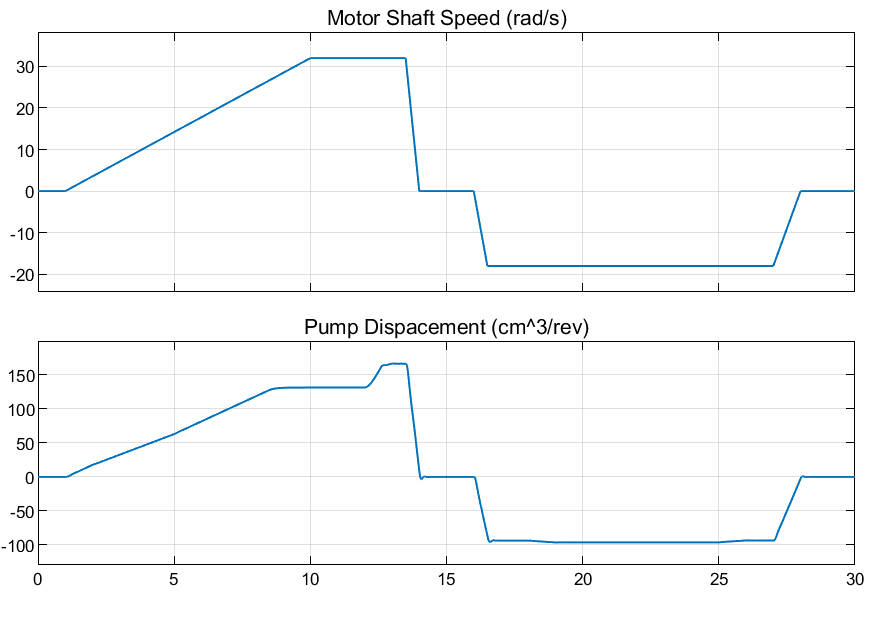

### 2. 补油

因为泵和马达运转会存在泄露(Pump Leakage,Motor Leakage子系统)，因此需要一个低压补油系统( Charge Pump子系统)。

当低压回路低于补油压力时，补油泵往回路中补油。

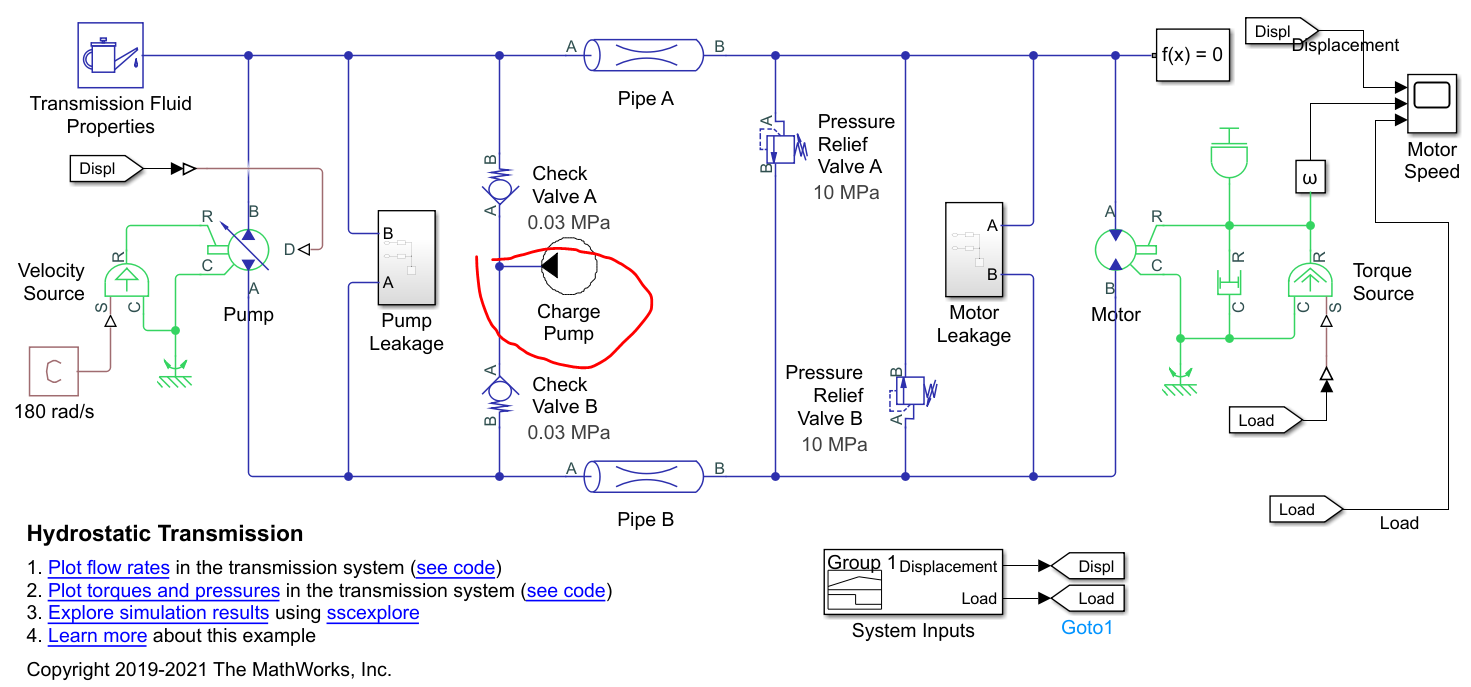

泵端泄露

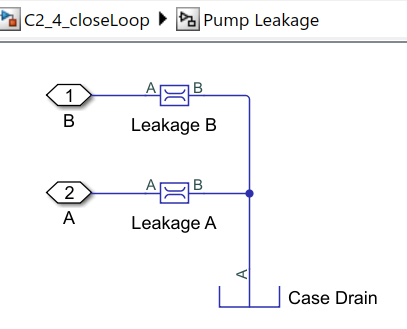

下图的为补油泵，一般补油压力0.7~1MPa.

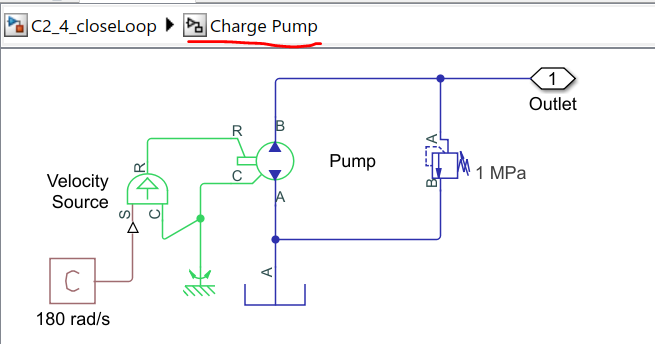

### 3. 高低压油路

液压泵的两条油路是高低压交替，两个溢流阀保证系统双向安全。

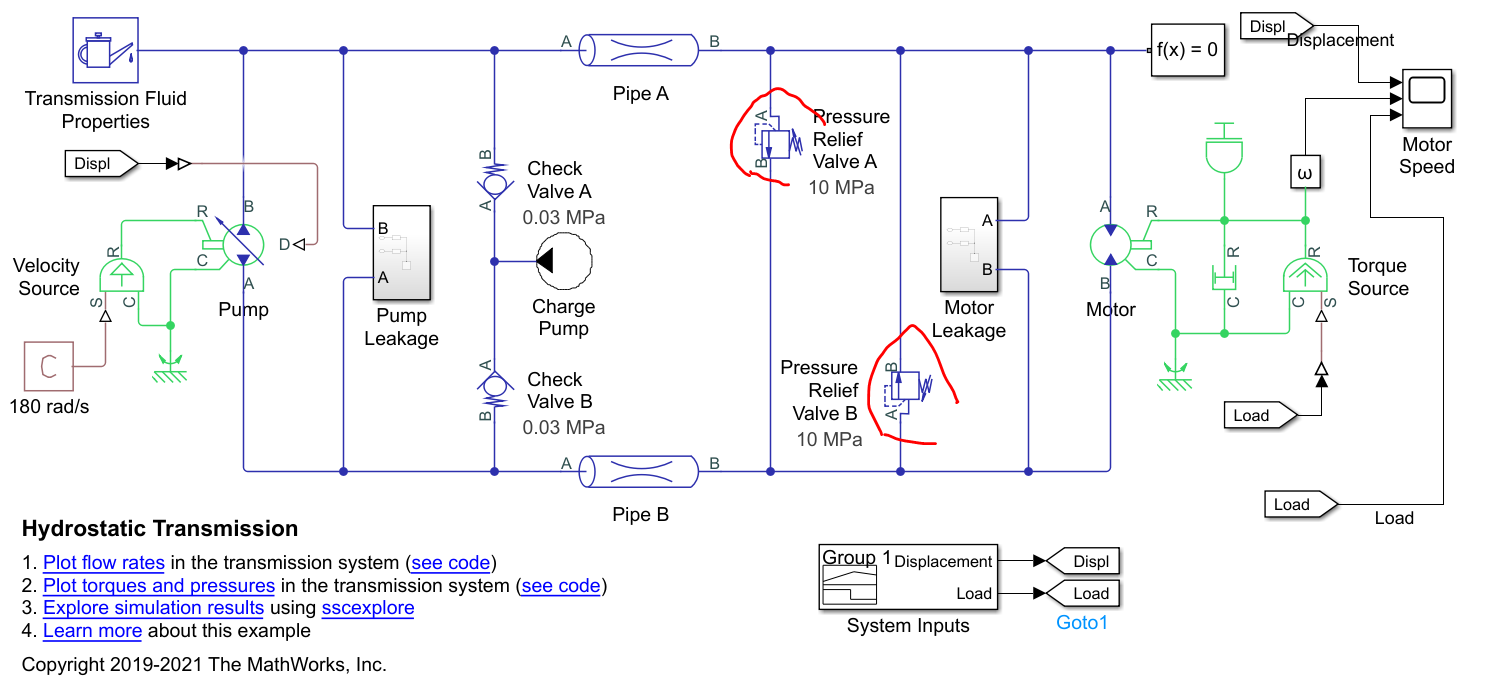

### 4. 查看结果

这是 System Inputs 定义的输入信号。

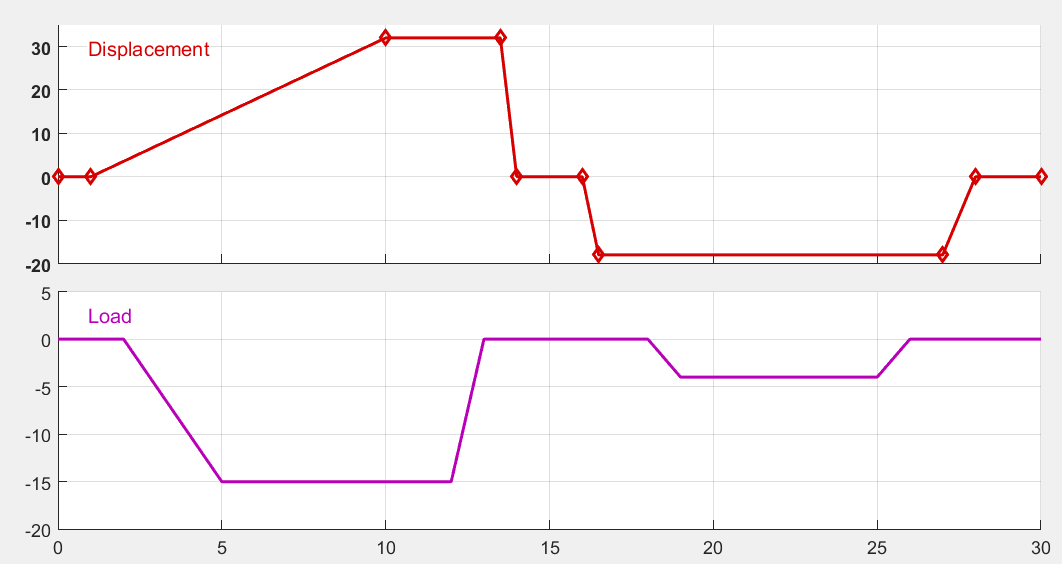

这是部分仿真结果曲线[Plot flow rates](matlab:sscfluids_hydrostatic_trans_plot1mdot)。

从下图可以看到，当主泵排量增加，Pump 流量增大，随之进入马达的流量也增加。

当高压油路超过了溢流阀A的设定压力，产生溢流。

- 可以看到下图Relief Valve A打开流量增加；

- 同时Motor的流量减少

- 15秒之后，反向供油时，高压油路没有超过溢流阀B的设定值，因此没有出现溢流；

补油

- 上方高压供油时，补油泵通过 Check Valve B 往下方低压油路补油；

- 15秒之后，反转时，补油泵通过Check Valve A往上方低压油路补油；

泄露

- Pump Leakage 以及 Motor Leakage 全程存在